clear
close all;
% DATA_Trip_File = xlsread("DATA_Trip_File.csv");
load('DATA_Trip_File.mat')


**Question 1-a**

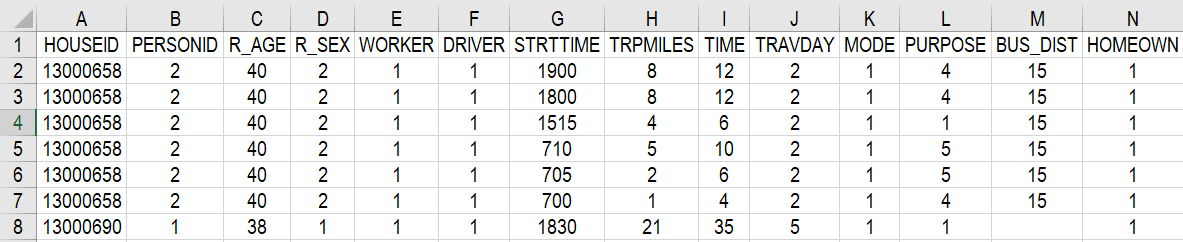

Position_3 = find(DATA_Trip_File(:,11)==3);% MODE=3
Position_4 = find(DATA_Trip_File(:,11)==4);% MODE=4
Position_6 = find(DATA_Trip_File(:,11)==6);% MODE=6
Position = [Position_3;Position_4;Position_6];

DATA_Trip_File_Public = DATA_Trip_File(Position,:);

**Question 1-b**

determine the most appropriate theoretical probability distributions to model each of  the following two random variables: (i) R_AGE and (ii) TRPMILES

close all;
Same_HouseID = diff(DATA_Trip_File_Public(:,1));
Same_PersonID = diff(DATA_Trip_File_Public(:,2));
Same_Person = (Same_HouseID == 0)&(Same_PersonID == 0);
Repetition_RowNum = find(Same_Person == 1)+1;
DATA_Trip_File_Public_Q1b = DATA_Trip_File_Public;
DATA_Trip_File_Public_Q1b(Repetition_RowNum,:) = [];

Age_Q1b = DATA_Trip_File_Public_Q1b(:,3);
TripMiles_Q1b = DATA_Trip_File_Public(:,8);

% figure(1)
% histogram(Age_Q1b,100)
% title('Histogram of Age in Q1b')
% grid on
% 
% figure(2)
% histogram(TripMiles_Q1b,100)
% title('Histogram of Trip Distance in Q1b')
% grid on

% For the variable of Age 

% Try Normal Distribution
pd_normal = fitdist(Age_Q1b,'Normal')

pd_normal =   NormalDistribution

  Normal distribution
       mu = 13.2434   [11.8085, 14.6784]
    sigma = 8.95389   [8.04785, 10.0916]


figure('Name','Histogram and Fitted Normal Distribution');
histogram(Age_Q1b,'Normalization','pdf')
pd_normal_x_axis = 0:0.1:max(Age_Q1b)+5;
pd_normal_y_axis = pdf(pd_normal,pd_normal_x_axis);
line(pd_normal_x_axis,pd_normal_y_axis)
t_normal = truncate(pd_normal,0,max(Age_Q1b))

t_normal =   NormalDistribution

  Normal distribution
       mu = 13.2434
    sigma = 8.95389
  Truncated to the interval [0, 69]


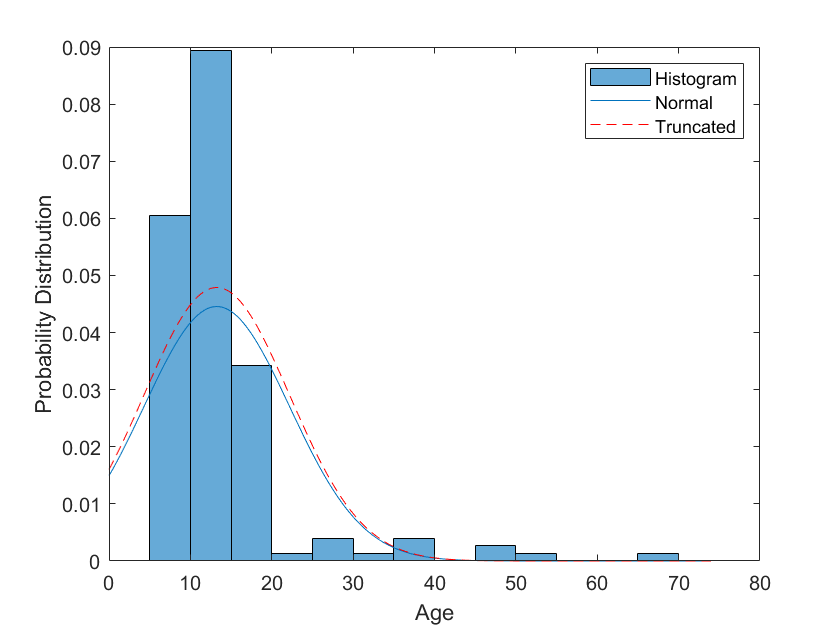

line(pd_normal_x_axis,pdf(t_normal, pd_normal_x_axis),'LineStyle','--', 'Color','red')
legend('Histogram','Normal','Truncated')
xlabel('Age')
ylabel('Probability Distribution')

nll_normal = negloglik(pd_normal)

nll_normal = 548.3760


% Try Exponential Distribution
pd_exp = fitdist(Age_Q1b,'Exponential')

pd_exp =   ExponentialDistribution

  Exponential distribution
    mu = 13.2434   [11.3667, 15.6293]


figure('Name','Histogram and Fitted Exponential Distribution');
histogram(Age_Q1b,'Normalization','pdf')
pd_exp_x_axis = 0:0.1:max(Age_Q1b)+5;
pd_exp_y_axis = pdf(pd_exp,pd_exp_x_axis);
line(pd_exp_x_axis,pd_exp_y_axis)
t_exp = truncate(pd_exp,0,max(Age_Q1b))

t_exp =   ExponentialDistribution

  Exponential distribution
    mu = 13.2434
  Truncated to the interval [0, 69]


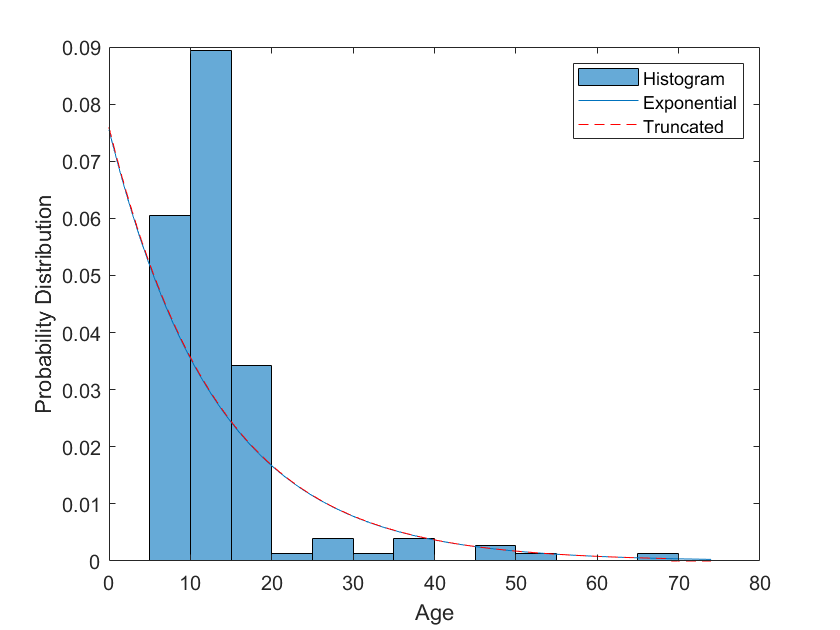

line(pd_exp_x_axis,pdf(t_exp, pd_exp_x_axis),'LineStyle','--', 'Color','red')
legend('Histogram','Exponential','Truncated')
xlabel('Age')
ylabel('Probability Distribution')

nll_exp = negloglik(pd_exp)

nll_exp = 544.6921


% Try Gamma Distribution
pd_Gamma = fitdist(Age_Q1b,'Gamma')

pd_Gamma =   GammaDistribution

  Gamma distribution
    a = 3.87216   [3.12044, 4.80497]
    b = 3.42017   [2.71618, 4.30661]


figure('Name','Histogram and Fitted Gamma Distribution');
histogram(Age_Q1b,'Normalization','pdf')
pd_Gamma_x_axis = 0:0.1:max(Age_Q1b)+5;
pd_Gamma_y_axis = pdf(pd_Gamma,pd_Gamma_x_axis);
line(pd_Gamma_x_axis,pd_Gamma_y_axis)
t_Gamma = truncate(pd_Gamma,0,max(Age_Q1b))

t_Gamma =   GammaDistribution

  Gamma distribution
    a = 3.87216
    b = 3.42017
  Truncated to the interval [0, 69]


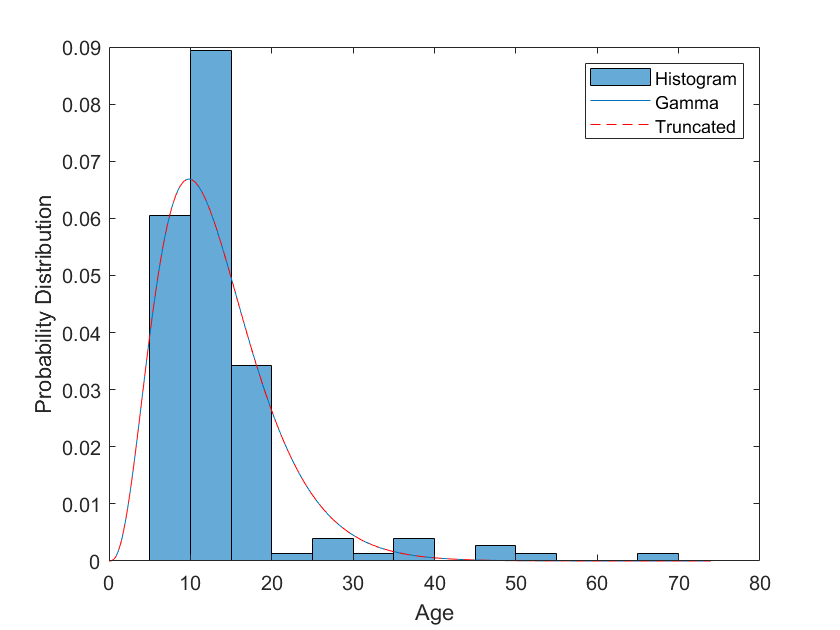

line(pd_Gamma_x_axis,pdf(t_Gamma, pd_Gamma_x_axis),'LineStyle','--', 'Color','red')
legend('Histogram','Gamma','Truncated')
xlabel('Age')
ylabel('Probability Distribution')

nll_Gamma = negloglik(pd_Gamma)

nll_Gamma = 491.5286

% For the variable of TRIMILE 

% Try Normal Distribution
pd_normal = fitdist(TripMiles_Q1b,'Normal')

pd_normal =   NormalDistribution

  Normal distribution
       mu = 6.69326   [5.5959, 7.79063]
    sigma = 9.51115   [8.79608, 10.3537]


figure('Name','Histogram and Fitted Normal Distribution');
histogram(TripMiles_Q1b,'Normalization','pdf')
pd_normal_x_axis = 0:0.1:max(TripMiles_Q1b)+5;
pd_normal_y_axis = pdf(pd_normal,pd_normal_x_axis);
line(pd_normal_x_axis,pd_normal_y_axis)
t_normal = truncate(pd_normal,0,max(TripMiles_Q1b))

t_normal =   NormalDistribution

  Normal distribution
       mu = 6.69326
    sigma = 9.51115
  Truncated to the interval [0, 100]


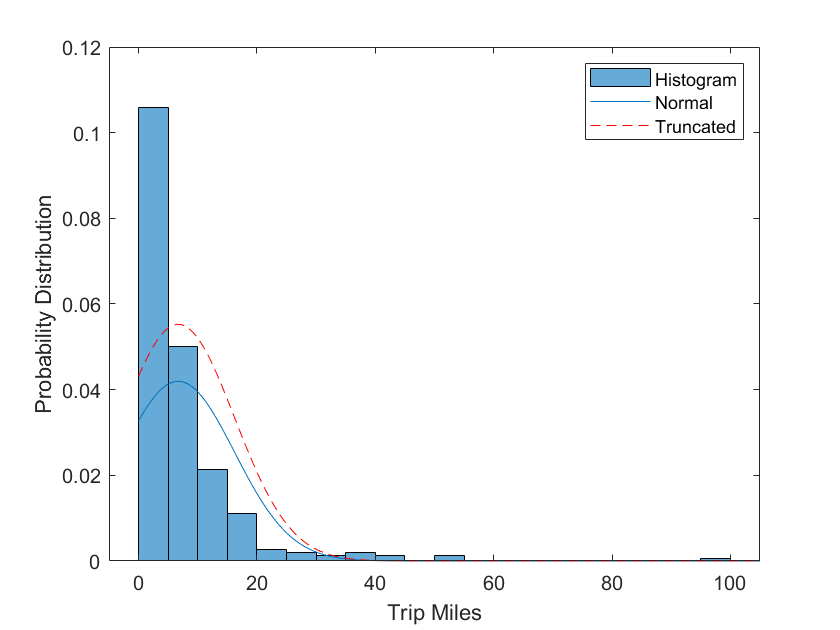

line(pd_normal_x_axis,pdf(t_normal, pd_normal_x_axis),'LineStyle','--', 'Color','red')
legend('Histogram','Normal','Truncated')
xlabel('Trip Miles')
ylabel('Probability Distribution')

nll_normal = negloglik(pd_normal)

nll_normal = 1.0679e+03


% Try Exponential Distribution
pd_exp = fitdist(TripMiles_Q1b,'Exponential')

pd_exp =   ExponentialDistribution

  Exponential distribution
    mu = 6.69326   [5.98621, 7.53412]


figure('Name','Histogram and Fitted Exponential Distribution');
histogram(TripMiles_Q1b,'Normalization','pdf')
pd_exp_x_axis = 0:0.1:max(TripMiles_Q1b)+5;
pd_exp_y_axis = pdf(pd_exp,pd_exp_x_axis);
line(pd_exp_x_axis,pd_exp_y_axis)
t_exp = truncate(pd_exp,0,max(TripMiles_Q1b))

t_exp =   ExponentialDistribution

  Exponential distribution
    mu = 6.69326
  Truncated to the interval [0, 100]


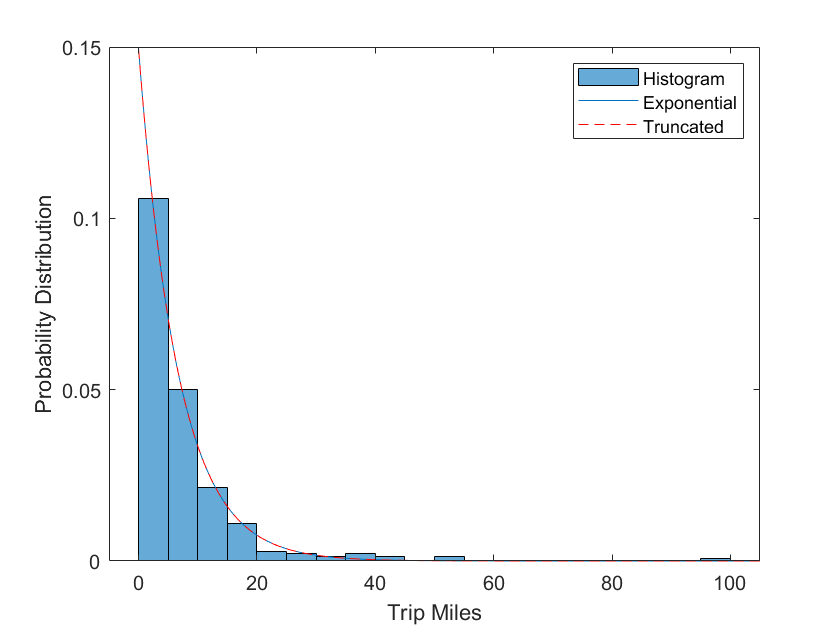

line(pd_exp_x_axis,pdf(t_exp, pd_exp_x_axis),'LineStyle','--', 'Color','red')
legend('Histogram','Exponential','Truncated')
xlabel('Trip Miles')
ylabel('Probability Distribution')

nll_exp = negloglik(pd_exp)

nll_exp = 844.2206


% Try Gamma Distribution
pd_Gamma = fitdist(TripMiles_Q1b,'Gamma')

pd_Gamma =   GammaDistribution

  Gamma distribution
    a = 0.930093   [0.806852, 1.07216]
    b =  7.19634   [5.97812, 8.66281]


figure('Name','Histogram and Fitted Gamma Distribution');
histogram(TripMiles_Q1b,'Normalization','pdf')
pd_Gamma_x_axis = 0:0.1:max(TripMiles_Q1b)+5;
pd_Gamma_y_axis = pdf(pd_Gamma,pd_Gamma_x_axis);
line(pd_Gamma_x_axis,pd_Gamma_y_axis)
t_Gamma = truncate(pd_Gamma,0,max(TripMiles_Q1b))

t_Gamma =   GammaDistribution

  Gamma distribution
    a = 0.930093
    b =  7.19634
  Truncated to the interval [0, 100]


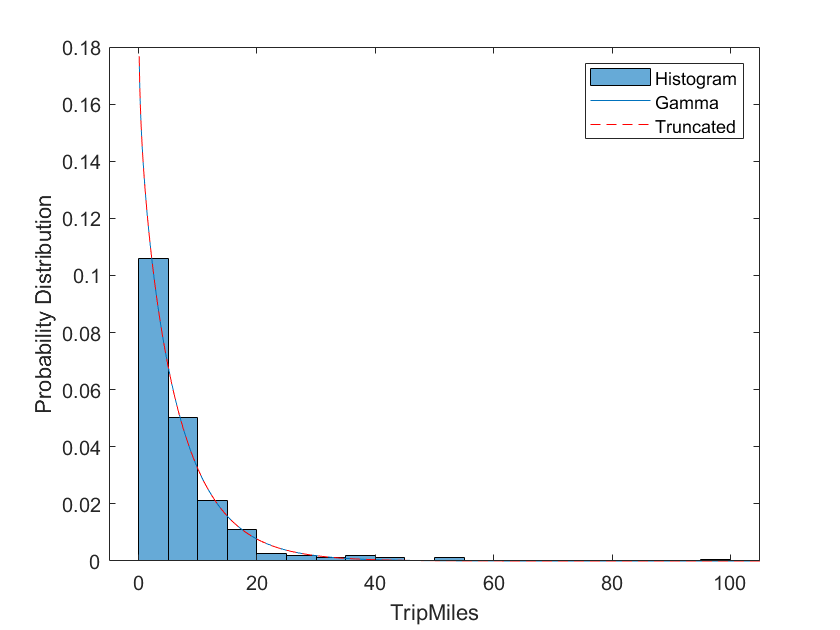

line(pd_Gamma_x_axis,pdf(t_Gamma, pd_Gamma_x_axis),'LineStyle','--', 'Color','red')
legend('Histogram','Gamma','Truncated')
xlabel('TripMiles')
ylabel('Probability Distribution')

nll_Gamma = negloglik(pd_Gamma)

nll_Gamma = 843.7113

**Question 1-c**

Construct a scatter plot of R_AGE versus the average TRPMILES that the person made on  their survey day

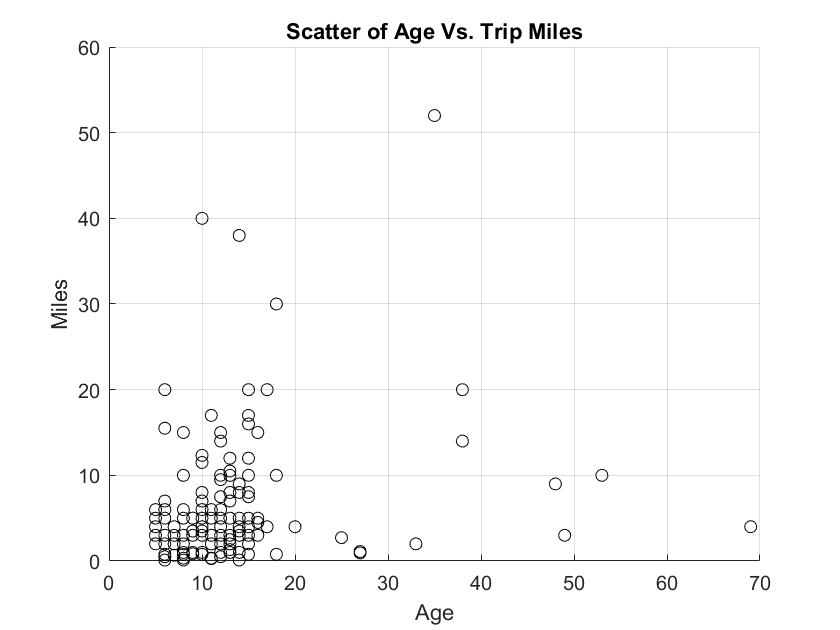

Same_Person_Completion = [0;Same_Person;0]; 

DATA_Trip_File_Public_Copy = DATA_Trip_File_Public; 
k = diff(Same_Person_Completion);           
ind = find(k==1)+1;            
num = find(k==-1)-ind+1;       
clear Average_TripMiles

for n = 1:length(ind)
        Person_Num = [ind(n)-1:1:ind(n)+num(n)-1];
        Average_Age(n) = mean(DATA_Trip_File_Public(Person_Num,3));
        Average_TripMiles(n) = mean(DATA_Trip_File_Public(Person_Num,8)) ;
        DATA_Trip_File_Public_Copy(Person_Num,:) = zeros;
end

Zero_Row_Num = find(DATA_Trip_File_Public_Copy(:,1)==0);
DATA_Trip_File_Public_Copy(Zero_Row_Num,:) = [];

Age_Q1c = [Average_Age,DATA_Trip_File_Public_Copy(:,3)'];
Average_TripMiles_Q1c = [Average_TripMiles,DATA_Trip_File_Public_Copy(:,8)'];


close all
figure(3)
scatter(Age_Q1c,Average_TripMiles_Q1c,'k')
title('Scatter of Age Vs. Trip Miles')
grid on
xlabel('Age')
ylabel('Miles')

% hold on
% scatter(DATA_Trip_File_Public_Copy(:,3),DATA_Trip_File_Public_Copy(:,8),'k')

**Question 1-d**

% Method I
Correlation_Coefficient = corrcoef(Age_Q1c,Average_TripMiles_Q1c)

Correlation_Coefficient =     1.0000    0.1947
    0.1947    1.0000



% Method II
Covariance_2 = cov(Age_Q1c,Average_TripMiles_Q1c);
Correlation_Coefficient_2 = Covariance_2/(std(Age_Q1c)*std(Average_TripMiles_Q1c))

Correlation_Coefficient_2 =     1.2150    0.1947
    0.1947    0.8231



% Method III
E_Age = mean(Age_Q1c);
E_Miles = mean(Average_TripMiles_Q1c);
Covariance_3 = mean((Age_Q1c-E_Age).*(Average_TripMiles_Q1c-E_Miles));
Correlation_Coefficient_3 = Covariance_3/(std(Age_Q1c)*std(Average_TripMiles_Q1c))

Correlation_Coefficient_3 = 0.1934



% Method IV
n = length(Age_Q1c);
xBar = mean(Age_Q1c);
yBar = mean(Average_TripMiles_Q1c);
numerator = 0;
for i = 1:n
numerator = numerator + (Age_Q1c(i) - xBar)*(Average_TripMiles_Q1c(i) - yBar);
end
Covariance_4 = numerator/(n-1) ;
Correlation_Coefficient_4 = Covariance_4/(std(Age_Q1c)*std(Average_TripMiles_Q1c))

Correlation_Coefficient_4 = 0.1947